# EE 451 Digital Signal Processing

# Homework 3

# Lisa Jacklin

# 9/15/2023

## Problem 1 : DSP: P&M 2.43

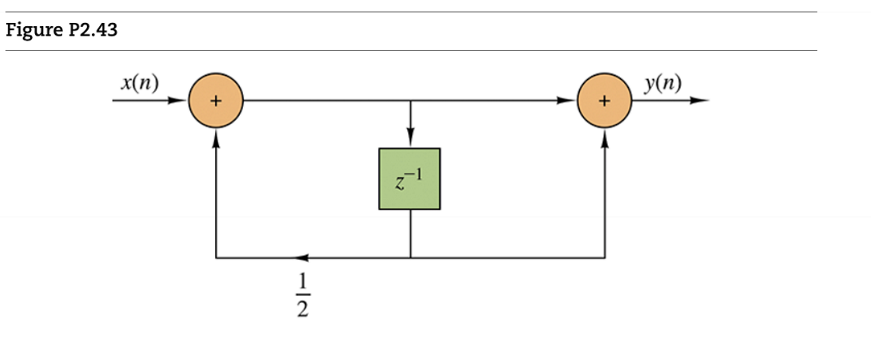

### A.compute the 10 first samples of its impulse 

To begin this problem, first writting this in a form that makes sense needs to happen...

y(n) = x(n) + 1/2x(n -1)

Now, using this equation, the first 10 samples can be determined, noting that x(n) is the impulse function.

y(n) = delta(n) + 1/2delta(n-1)

y(0) = delta(0) + 1/2(delta(0-1) = 1 + 1/2(0) = 1

y(1) = delta(1) + 1/2(delta(1-1)) = 0 + 1/2(1) = 1/2

y(2) = delta(2) + 1/2delta(2-1) = 0 + 1/2(0) = 0

y(3) through y(10) will be equal to zero, as x(n) is meantioned as being the impulse, and only for delta of zero, is the impulse function greater than zero.

### B. Find the input-output relation

Now, comparing the input n to the output y(n), we get two different ranges which are shown below:

n = [0 1 2 3 4 5 6 7 8 9 10]

y(n) = [ 1 1/2 0 0 0 0 0 0 0  0]

to get the input/output relation, these two are compared giving the relation below:

r = [-1 1/2 2 3 4 5 6 7 8 9 10]

### C. Apply the input x(n) = {1, 1, 1, ...} and compute the first 10 samples of the output. 

Now, when considering x(n) has the set of all ones, and that y(n) is to be determined, using the same equation as before, the first 10 samples are calculated.

Note that the very first 1 is x(0)

y(n) = x(n) + 1/2x(n -1)

y(0) = x(0) + 1/2x(0-1) = 1 + 1/2(1) = 3/2

y(1) = x(1) + 1/2x(1-1) = 1 + 1/2(1) = 3/2

y(2) = x(2) + 1/2x(2-1) = 1 + 1/2(1) = 3/2

and this pattern of 3/2 continues from y(3) to y(10).

### D. compute the first 10 samples of the output for the input given in part(c) by using convolution.

Now, using matlab and noting that x(n) in part C is a step function, the function answers is given. Note that for x(n-1) that I used stepseq.m in order to gather the correct numbers.

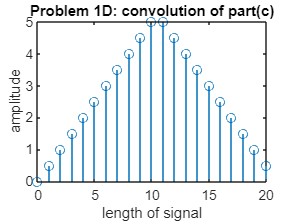

x1a = [ones(1, 10)]; 
x1b = 1/2 .* stepseq(1, 0, 11);
n = 0:1:20;
y = conv(x1a, x1b);

stem(n,y);
title("Problem 1D: convolution of part(c)");
xlabel("length of signal"); ylabel("amplitude");

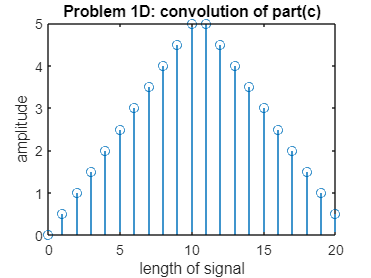

### E.Is the system causal? Is it stable?

This system is causal and stable as there is a limit to both x and y, and although it may spread to infinity on either side, the system will eventually go to zero.

## Problem 2: DSP:P&M 2.49

### 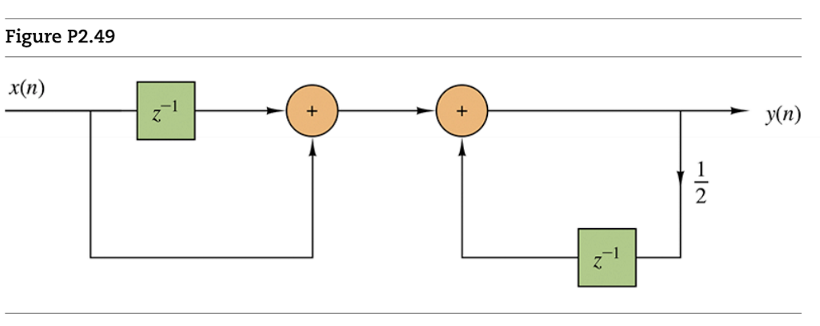

### A. Determine the impulse response h(n)

Just like in Problem 1 part a, I need to first create an equation that can be used to discribe this format above...

y(n) = x(n-1) + 1/2x(n-1)

h(n) = y(n)/x(n) = 1 + 1/2n

### B. show that h(n) is equal to the convolution of the following signals: h1(n) = delta(n) + delta(n-1), h2(n) = (1/2)^nu(n)

n = 0:1:10; %timing range for response

h1a = impseq(0, 0, 10);

x = 1×11 logical array
   1   0   0   0   0   0   0   0   0   0   0


h1b = impseq(1, 0, 10);

x = 1×11 logical array
   0   1   0   0   0   0   0   0   0   0   0


h1 = sigadd(h1a, n, h1b, n);

n =      0     1     2     3     4     5     6     7     8     9    10



h2a = (1/2).^n;
h2b = stepseq(0, 0, 10);
h2 = sigadd(h2a, n, h2b, n);

n =      0     1     2     3     4     5     6     7     8     9    10


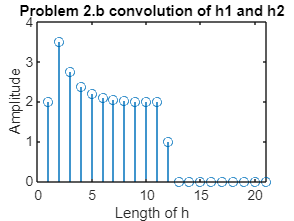


%now that the two signals have been established, doing the convolution of
%these two signals must be done and displayed in order to compare that part
%B is equal to part A.

prob2h = conv(h2, h1);

stem(prob2h);
title("Problem 2.b convolution of h1 and h2");
xlabel("Length of h"); ylabel("Amplitude")

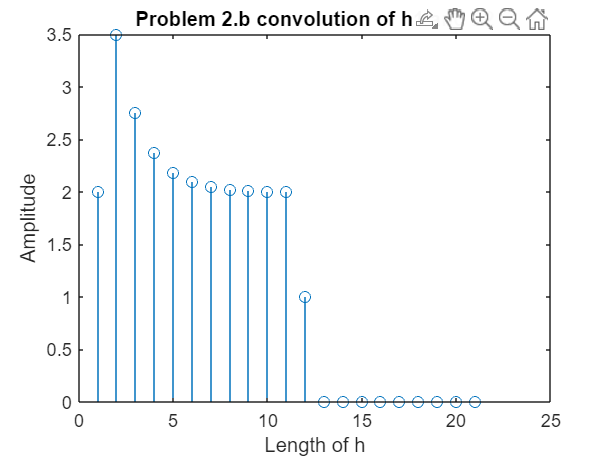

## Problem 3 DSP:P&M 3.13 Let x(n) be a sequence with z-transform X(z). Determine, in terms of X(z), the z-transforms of the following signals.

### A. x1(n) = x(n/2) if n is even, 0 if n is odd. 

To begin this problem, I started out by writing this out in a way that would make the equation in part a true with the help of the unit step equation.

xa(n) = x(n/2)*u(n)

From here I can begin taking the Z-transform.

xa(n) = x(n/2)*u(n)

Xa(z) = Z[x(n/2)*u(n)] noting that there is a time shift here...

Xa(z) = X(z^2) 

Keep in mind that the n/2 results in z^2 in the equation above, which is our result.

### B.x2(n) = x(2n)

Following the same form as in part a:

x2(n) = x(2n)

X2(z) = Z[x(2n)]

Note that there is a time scaling here too.

X2(z) = X(z/2)

Similar to how it was in part a, 2n results in z/2.

Thus the z-transform of: 

 x2(n) = x(2n) = X2(z) = X(z/2)

## Problem 4 DSP:P&M 3.16 determine the convolution of the following pairs of signals by means of the z-transform

### A. x1(n) = (1/4)^nu(n-1), x2(n) = [1 + (1/2)^n]u(n)

To begin this, I will be taking the z-transform of each equation individually:

x1(n) = (1/4)^n*u(n-1)

x2(n) = (1 + (1/2)^n)*u(n)

Starting with x1(n):

x1(n) = (1/4)^n*u(n-1)

X1(z) = (1/4)*z^-1 / (1 - 1/4*z^-1)

And then the transform of x2(n):

x2(n) = (1 + (1/2)^n)*u(n)

X2(z) = (1/(z^-1)) + 1/2/((1 - 1/2*z^-1))

Now, for convolution which is Y(z) = X1(z) *X2(z):

Y(z) = [(1/4)*z^-1 / (1 - (1/4)*z^-1)] *(1/(z^-1)) + 1/2/((1 - 1/2*z^-1))

Y(z) = [(1/4)*z^-1/(1-z^(-1/4)] *[1/(1-z^-1) + (1/2)/(1-z^(-1/2))]

### B. x1(n) = u(n), x2(n) = delta(n) + (1/2)^nu(n)

Using the same format as in A:

x1(n) = u(n)

X1(z) = 1/(1-z^-1)

x2(n) = delta(n) + (1/2)^n*u(n)

X2(z) = 1 + (1/2*z^-1)/(1-z^-1)

Now for the convolution Y(z)

Y(z) = X1(z) * X2(z)

Y(z) = [1/(1-z^-1)] * [1 + (1/2*z^-1/(1-z^-1)]

Y(z) = (1 + (1/2)*z^-1)/(1-z^-z)

### C. x1(n) = (1/2)^nu(n), x2(n) = cos(pin)u(n)

x1(n) = (1/2)^n*u(n)

X1(z) = (1/2)*z^-1 /(1-z^-1)

x2(n) = cos(pi*n)*u(n)

X2(z) = 1 + sumation[cos(pi*n)*u(n)*z^-n)....

Y(z) = X1(z)*X2(z)

Y(z) = [(1/2)*z^-1 /(1-z^-1)]*[ 1 + sumation[cos(pi*n)*u(n)*z^-n)]

### D.x1(n) = nu(n), x2(n) = 2^nu(n-1)

x1(n) = n*u(n)

X1(z) = -z * [-1 * (-z^-2) / (1 - z^-1)^2] 

X1(z) =( z^-1)/(1-z^-1)^2

x2(n) = 2^n*u(n-1)

X2(z) = 2 * 1/(z-2) = 2/(z-2)

Y(z) = X1(z) * X2(z)

Y(z) = ( z^-1)/(1-z^-1)^2 *  2/(z-2)

Y(z) = 2*(z^-1)/[ (1-z^-1)^2*(z-2)]

## Problem 5 DSP:P&M 3.20

### A. Draw the pole-zero pattern for the signal x1(n) = r^nsin(w0n)U(n), 0 <r<1

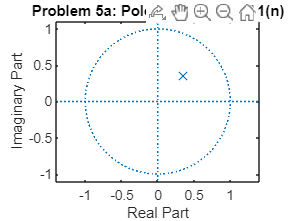

%since we are given the range of r which should be between 0 and 1, I
%choose right in the middle for r.
r = 0.5;
%next for the purpose of testing the pole-zero pattern, I am setting a w0
%value
w0 = pi/4;

%then, defining the numer. and denomin. which are a and b respectfully
a = [0 sin(w0)];
b = [1 (-r * exp(1i* w0))];

%from a and b we can then plot the zplane
zplane(a,b);
title('Problem 5a: Pole-Zero plot for x1(n)')

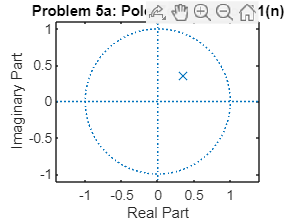

### B. compute the z-transform X2(z), which corresponds to the pole-zero pattern in part(a).

H(z) = B(z)/A(z) = (z-z1) /(z-p1)(z-p2)

Note that z1 is the zero and p1 and p2 are the poles.

Also note that X2(z) = H(z)*X1(z) in this case. so first, the X1(z) must be calcualted from x1(n)

 x1(n) = r^n*sin(w0*n)*U(n)

X1(z) = z*sin(w0)/(z - r*exp(jw0)

And since we don't have any poles, but we have a single zero which for convinence, I will refer to as 0.5i + 0.5, we can plug this into H(z)

X2(z) = [(z-0.5i+0.5)] *[z*sin(w0)/(z - r*exp(jw0)]

### C.compare X1(z) with X2(z). Are they identical? If not, indicate a method to derive X1(z) from the pole-zero pattern.

When comparing X1(z) and X2(z) the difference lies in the H(z) value which is (z +0.5i + 0.5). Aside from this piece, the two equations are practically identical.

In the case that these two were not identical, finding and repositioning the poles and zeros would allow the two equations to become identical.